## Import Data

Import training and validation data.

imdsTrain = imageDatastore("F:\Data227","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% % Load Network
load trainedNetwork_1

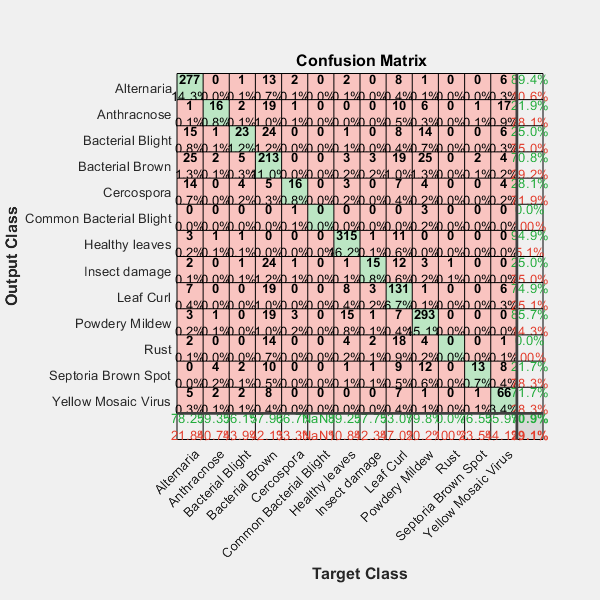

% Classify Validation Images
[testData]=splitEachLabel(imdsTrain,0.3,'randomize');
allclass=[];
for ii=1:length(testData.Labels)
    I=readimage(testData,ii);
    % % Done Classification
       class=classify(trainedNetwork_1,I);
       % figure(5),
       % subplot(8,8,ii)
       % imshow(I)
       % title(char(class))
       allclass=[allclass class];
end
figure,plotconfusion(allclass,testData.Labels')

% layer=7;
YValidation=testData.Labels;
Ypred=allclass;
accuracy=sum(Ypred==YValidation')/numel(YValidation);
Cpredicted=allclass;
C=confusionmat(YValidation,Cpredicted);
OverallAccTst=sum(YValidation==Cpredicted)/length(Cpredicted);
Acc=zeros(2,1);
Sens=zeros(2,1);
Spec=zeros(2,1);
Prec=zeros(2,1);
F1Sc=zeros(2,1);
FPR=zeros(2,1);
MCC=zeros(2,1);
ERate=zeros(2,1);
for i=1:length(C)
    TP=C(i,i);
    TN=sum(C(:))-sum(C(:,i))-sum(C(i,:))+C(i,i);
    FP=sum(C(:,i))-C(i,i);
    FN=sum(C(i,:))-C(i,i);
    Acc(i)=(TP+TN)/(TP+TN+FP+FN);
    Sens(i)=TP/(TP+FN);
    Spec(i)=TN/(FP+TN);
    Prec(i)=TP/(TP+FP);
    F1Sc(i)=2*TP/(2*TP+FP+FN);
    S=(TP+FN)/sum(C(:));
    P=(TP+FP)/sum(C(:));
    MCC(i)=(TP/sum(C(:))-S*P)/sqrt(S*P*(1-S)*(1-P));
    ERate(i)=1-Acc(i);
    FPR(i)=1-Spec(i);
end
disp('Accuracy')

Accuracy


fprintf('The acc is : %f \n',Acc);

The acc is : 0.943387 
The acc is : 0.965003 
The acc is : 0.955224 
The acc is : 0.874936 
The acc is : 0.974781 
The acc is : 0.997941 
The acc is : 0.971693 
The acc is : 0.971179 
The acc is : 0.917653 
The acc is : 0.936696 
The acc is : 0.976325 
The acc is : 0.973752 
The acc is : 0.959856 



disp('Sensitivity')

Sensitivity


 sprintf('The Sensitivity is : %f \n', Sens)

ans =     'The Sensitivity is : 0.893548 
     The Sensitivity is : 0.219178 
     The Sensitivity is : 0.250000 
     The Sensitivity is : 0.707641 
     The Sensitivity is : 0.280702 
     The Sensitivity is : 0.000000 
     The Sensitivity is : 0.948795 
     The Sensitivity is : 0.250000 
     The Sensitivity is : 0.748571 
     The Sensitivity is : 0.856725 
     The Sensitivity is : 0.000000 
     The Sensitivity is : 0.216667 
     The Sensitivity is : 0.717391 
     '


disp('Specificity')

Specificity


sprintf('The Specificity is: %f \n', Spec)

ans =     'The Specificity is: 0.952848 
     The Specificity is: 0.994118 
     The Specificity is: 0.990276 
     The Specificity is: 0.905603 
     The Specificity is: 0.995758 
     The Specificity is: 1.000000 
     The Specificity is: 0.976412 
     The Specificity is: 0.994158 
     The Specificity is: 0.934389 
     The Specificity is: 0.953779 
     The Specificity is: 0.999473 
     The Specificity is: 0.997876 
     The Specificity is: 0.971907 
     '


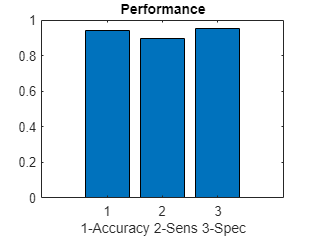

figure
bar([Acc(1) Sens(1) Spec(1)])
xlabel('1-Accuracy 2-Sens 3-Spec')
title('Performance');

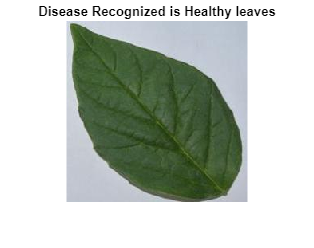

Accuracy=Acc';
Precision=Prec';
Recall=Sens';
% Read image for Classification
[filename,pathname]=uigetfile('*.*','Select the Input Image');
file=strcat(pathname,filename);
Inputimage=imread(file);
figure
imshow(Inputimage)
% Classifiy the image using the network
label=classify(trainedNetwork_1,Inputimage);
title(['Disease Recognized is ', char(label)])